# Question 4

## PDF and Histogram

## Generate a 1000 uniformly distribution samples from a Normal/ Gaussian density with mean 0 and variance 1, x~N(0,1) using the randn function.

## Generated a random vector, Gaussian random numbers and draw a histogram a = randn(1,5000).Then we divide the number of counts t by the total number of times the bin size 5000*0.2. This will guarantee the total area of the boxes over the whole line is normalized to 1.

a = randn(1,5000)

a =     0.5377    1.8339   -2.2588    0.8622    0.3188   -1.3077   -0.4336    0.3426    3.5784    2.7694   -1.3499    3.0349    0.7254   -0.0631    0.7147   -0.2050   -0.1241    1.4897    1.4090    1.4172    0.6715   -1.2075    0.7172    1.6302    0.4889    1.0347    0.7269   -0.3034    0.2939   -0.7873    0.8884   -1.1471   -1.0689   -0.8095   -2.9443    1.4384    0.3252   -0.7549    1.3703   -1.7115   -0.1022   -0.2414    0.3192    0.3129   -0.8649   -0.0301   -0.1649    0.6277    1.0933    1.1093


binsize = [10,20,30,35,40,50,60]

binsize =     10    20    30    35    40    50    60


## The hist divides the interval [min(x), max(x)] into the binsize code and yields the output[t,u] where t is the vector whose elements are numbers of samples in each bin, and u is a vector whose elements are the centers of the bins. Plot the Histogram using the bar function and this code displays a bar graph in order to examine the trends rising  or falling in one or more variables over a period of time.

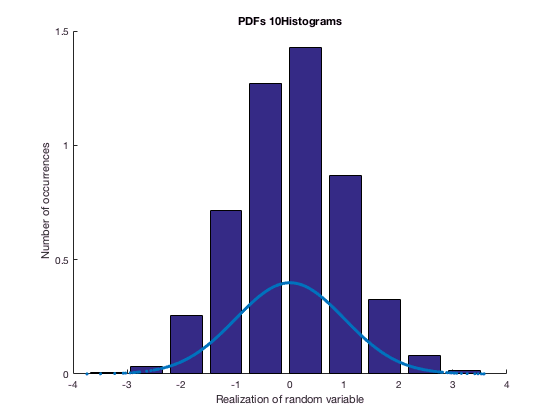

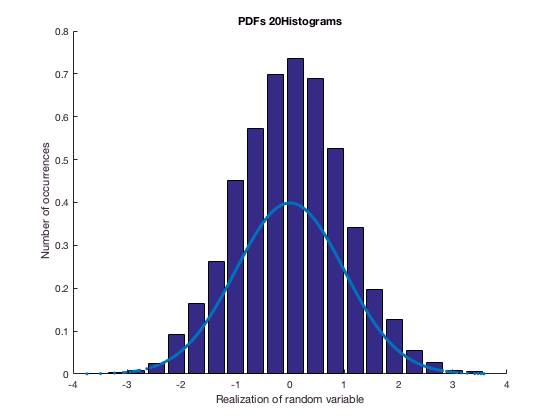

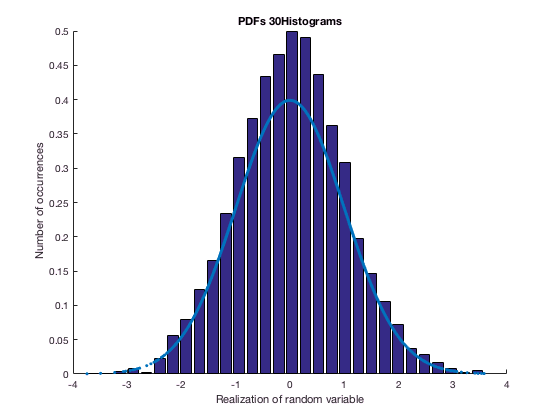

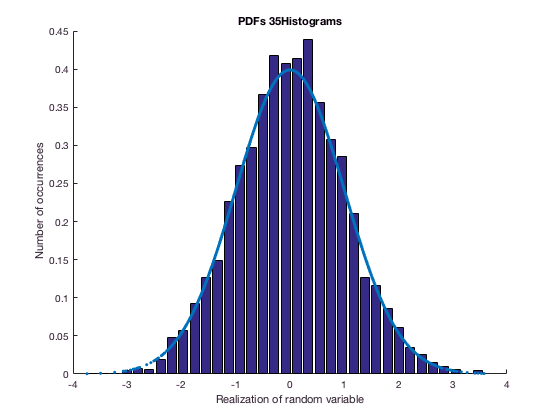

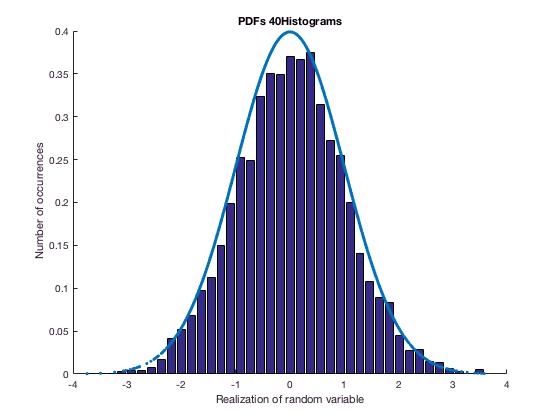

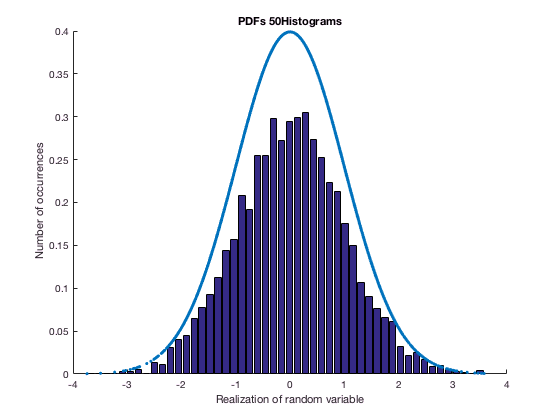

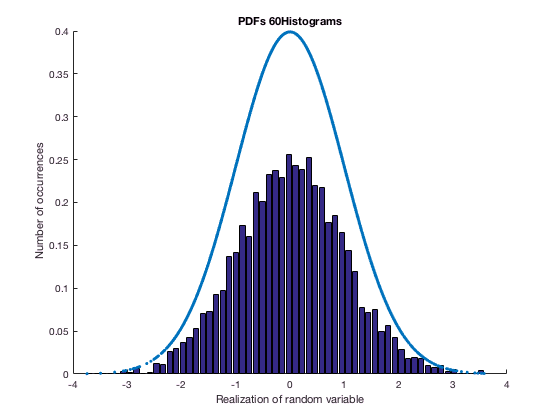

for j   = binsize
   [t,u]   = hist(a,j);
   
figure
hold on
bar(u,t/(5000*.2)) 
plot(a,exp(-a.^2/2)/sqrt(2*pi),'.')
xlabel('Realization of random variable')
ylabel(' Number of occurrences')
title(['PDFs ',num2str(j),'Histograms'])
hold off
end    

## The graph with the best fit would be the graph with 35 thru 40 bins.The samples you would expect to fall in a histogram bin width centered at x would be p(x) where p(x) is the probability density function. The trade-offs in choosing the number of histogram is that the higher the number of bins the more likely the bins fit in the curve. The only thing is when choosing the number of bins is if, its too large lose detail, too small there not enough samples. Picking a range of numbers of bins would be the best fit. Within that range of numbers the 35 thru 40 number of bins has a good approximation within the curve. Overall,  35 bins is the best number of bins because it is within the curve of the histogram plot.